clc
clear
data = readtable('../data/train.csv', 'ReadVariableNames', true);

%% Asignar variables
y = data{:,1};              % Variable dependiente (0,1)
X1 = data{:,2};             % Valores numéricos (unidades)
X2 = data{:,3};             % Valores numéricos (décimas)
X3 = data{:,4};             % Días de la semana (categóricos)
X4 = data{:,5};             % Valores numéricos (unidades)
X5 = data{:,6};             % Valores numéricos (centenas)
X6 = data{:,7};             % Estados de EE.UU (categóricos)
X7 = data{:,8};             % Marcas de carros (categóricos)% Identificar y mostrar valores faltantes

summary(data);

Variables:

    y: 6973×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    x1: 6973×1 double

        Values:

            Min       -2.8601 
            Median     2.8646 
            Max        10.754 

    x2: 6973×1 double

        Values:

            Min        14.421 
            Median     20.011 
            Max        26.281 

    x3: 6973×1 cell array of character vectors

    x4: 6973×1 double

        Values:

            Min             -4.3386    
            Median          -0.005903  
            Max             4.5536     
            NumMissing      428        

    x5: 6973×1 double

        Values:

            Min             53.441  
            Median          100.72  
            Max             147.31  
            NumMissing      876     

    x6: 6973×1 cell array of c



missingData = ismissing(data);
figure;

% Crear una tabla para el heatmap
missingTable = array2table(missingData, 'VariableNames', data.Properties.VariableNames);

numMissing = sum(missingData);
% Calcular el porcentaje de datos faltantes por columna
numRows = size(data, 1);  % Número total de filas
percentMissing = (numMissing / numRows) * 100;

% Mostrar el porcentaje de datos faltantes por columna
disp(percentMissing)

         0         0         0         0    6.1380   12.5627   17.7112   22.5441




%heatmap(missingTable, 'Mapa de Datos Faltantes', 'XLabel', 'Variables', 'YLabel', 'Observaciones');

% Calcular estadísticas
stats = varfun(@mean, data(:,[2 3 5 6]), 'OutputFormat', 'table'); % Media
disp(stats);

    mean_x1    mean_x2    mean_x4    mean_x5
    _______    _______    _______    _______

    3.0142     20.007       NaN        NaN  



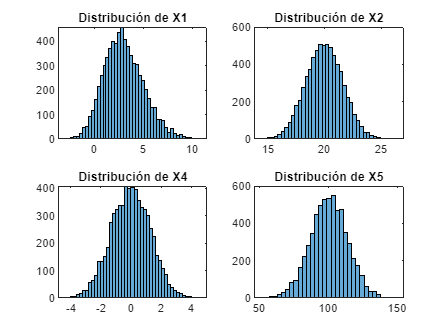


%% Visualizar distribución
%figure;
subplot(2,2,1); histogram(X1); title('Distribución de X1');
subplot(2,2,2); histogram(X2); title('Distribución de X2');
subplot(2,2,3); histogram(X4); title('Distribución de X4');
subplot(2,2,4); histogram(X5); title('Distribución de X5');

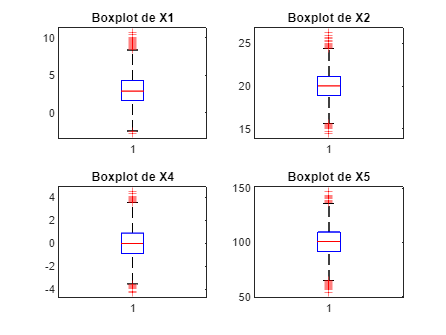


figure;
subplot(2,2,1); boxplot(X1); title('Boxplot de X1');
subplot(2,2,2); boxplot(X2); title('Boxplot de X2');
subplot(2,2,3); boxplot(X4); title('Boxplot de X4');
subplot(2,2,4); boxplot(X5); title('Boxplot de X5');

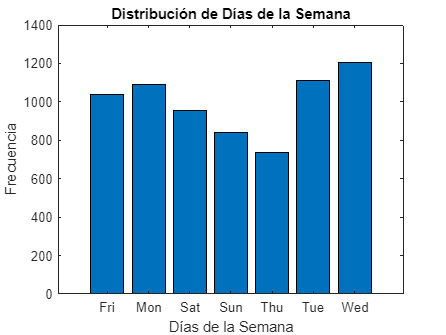


%% Distribución de X3 (días de la semana)
X3_categorical = categorical(X3); % Asegúrate de que X3 es categórico
dayCounts = countcats(X3_categorical); % Contar las ocurrencias

% Obtener los nombres únicos de las categorías (días de la semana)
dayNames = categories(X3_categorical);

% Graficar las frecuencias con bar
figure;
bar(dayCounts);
set(gca, 'XTickLabel', dayNames); % Asignar etiquetas a los ejes X
title('Distribución de Días de la Semana');
xlabel('Días de la Semana');
ylabel('Frecuencia');

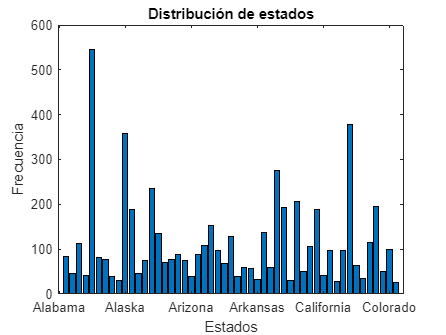


%%  Distribución de X6 (estados de EE.UU.)
X6_categorical = categorical(X6); % Asegúrate de que X3 es categórico
stateCounts = countcats(X6_categorical); % Contar las ocurrencias

% Obtener los nombres únicos de las categorías (días de la semana)
StateNames = categories(X6_categorical);

% Graficar las frecuencias con bar
figure;
bar(stateCounts);
set(gca, 'XTickLabel', StateNames); % Asignar etiquetas a los ejes X
title('Distribución de estados');
xlabel('Estados');
ylabel('Frecuencia');

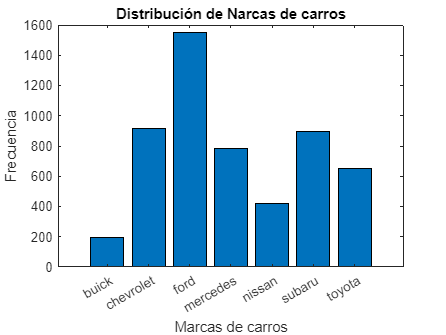


%% Distribución de X7 (marcas de carros)
X7_categorical = categorical(X7); % Asegúrate de que X3 es categórico
carCounts = countcats(X7_categorical); % Contar las ocurrencias

% Obtener los nombres únicos de las categorías (días de la semana)
CarsNames = categories(X7_categorical);

% Graficar las frecuencias con bar
figure;
bar(carCounts);
set(gca, 'XTickLabel', CarsNames); % Asignar etiquetas a los ejes X
title('Distribución de Narcas de carros');
xlabel('Marcas de carros');
ylabel('Frecuencia');

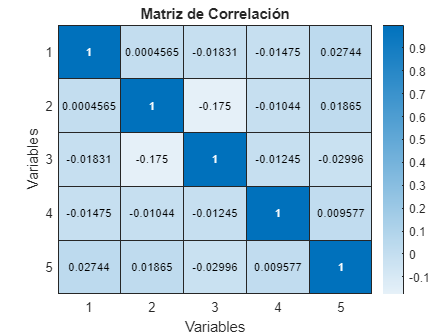


%% Matriz de correlación
numVars = [X1 X2 X4 X5 y]; % Solo variables numéricas
corrMatrix = corr(numVars, 'rows', 'pairwise');

% Mostrar matriz
figure; heatmap(corrMatrix, 'Title', 'Matriz de Correlación', ...
    'XLabel', 'Variables', 'YLabel', 'Variables');figure;

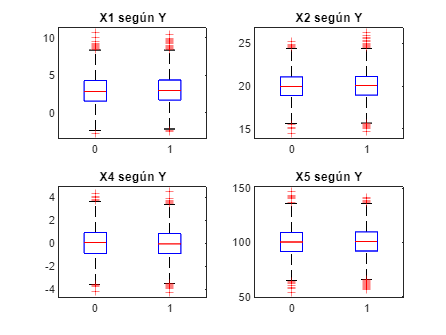

subplot(2,2,1); boxplot(X1, y); title('X1 según Y');
subplot(2,2,2); boxplot(X2, y); title('X2 según Y');
subplot(2,2,3); boxplot(X4, y); title('X4 según Y');
subplot(2,2,4); boxplot(X5, y); title('X5 según Y');